# Integration and Test

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

After sorting all of the puzzle pieces, assembling them should be simple, right? But in engineering, building a complex system is a very intricate process. Once individual subsystems and components have been designed and tested in isolation, the next challenge is to methodically bring them together, ensuring seamless interaction and performance, known as integration. The Integration and Test phase of problem solving provides a structured approach to validating that each component functions not just independently, but as part of a cohesive whole. By evaluating the interactions between systems, engineers can identify and resolve inconsistencies before finalizing the product. Just as decomposition clarifies complexity, integration confirms functionality, bringing all elements together into a reliable, working product. In this script, we will examine how integration and test aids in validating a product's design for final acceptance by the customer.

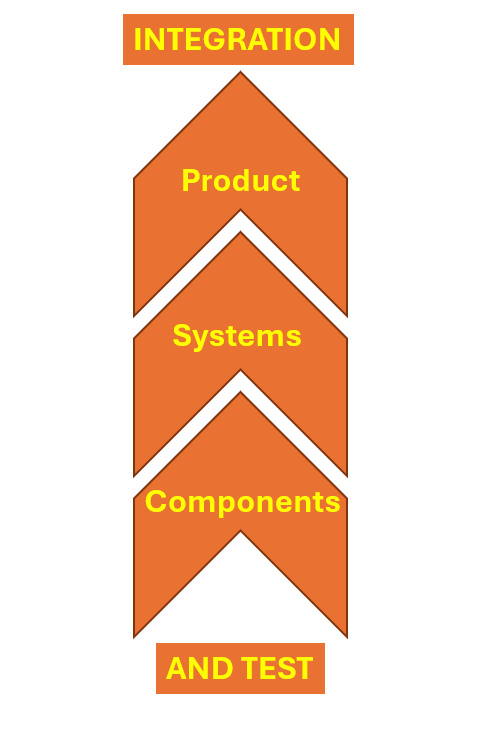

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Integrating a solution

Building off of the [decomposition discussion](matlab:open('./SystemsDecomposition.mlx')), imagine all the car parts have now been developed and it is time to assemble them to create a functional car. It's very difficult to assemble parts together without understanding how they work together. Solving complex systems or problems can be achieved in stages by integration. Integration combines smaller solutions into larger, more defined systems, with the goal of validating that each system meets its requirements. The right side of the V-model demonstrates the process of integrating a solution. After engineering development is completed, the next stage in the integration process are the components; which are the actionable tasks that were defined during the decomposition phase. At this stage, component testing occurs in support of validating its operational requirements. The next stage is the systems integration and testing, where two systems are connected at the interfaces and tested to understand how they operate simultaneously. At the final stage, the full product is tested; where all systems and components are integrated together with the intent of fulfilling the original problem statement and high level requirements. Systems and components will also have requirements associated with them, with all requirements traceable up and down the right side of the V-model. The diagram below illustrates the V-model integration path:

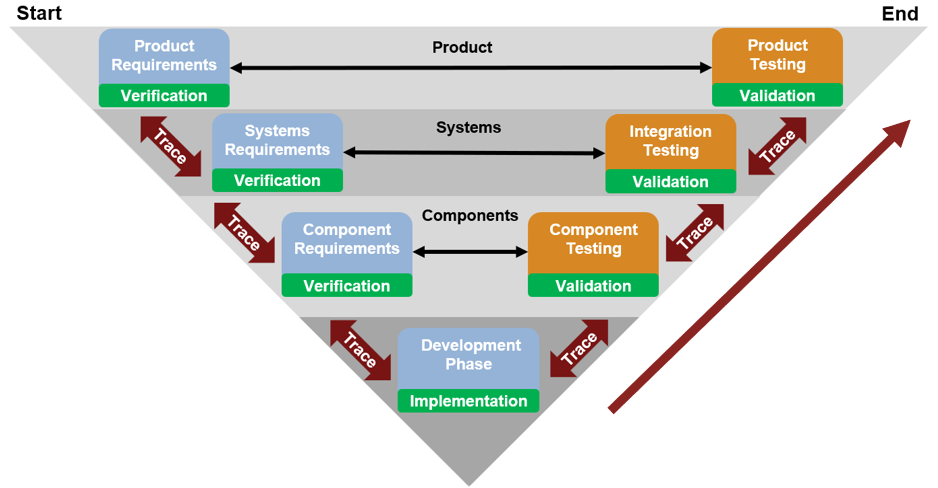

 **Exercise 1. **What is the main purpose of the integration and test phase in solving a complex problem? Please select **one** option and click the **Submit Answer** button below. 

exerciseSol1(...
    A = false, ...
    B = true, ...
    C = false, ...
    D = false);

Correct! The goal is to combine components and systems into one functional system.


## Solution Integration: Delivery Drone

We will explore the problem-solving techniques we have learned up to this point and apply them to package delivery using a quadcopter. Those techniques include problem statements, requirements, tests and decomposition for this product. Since we are at the stage of integrating the solution for a delivery drone, these techniques will be applied in layers as described in the V-model. The goal is to integrate individual components and then systems before the full integration at the product level, as described in the following system architecture:

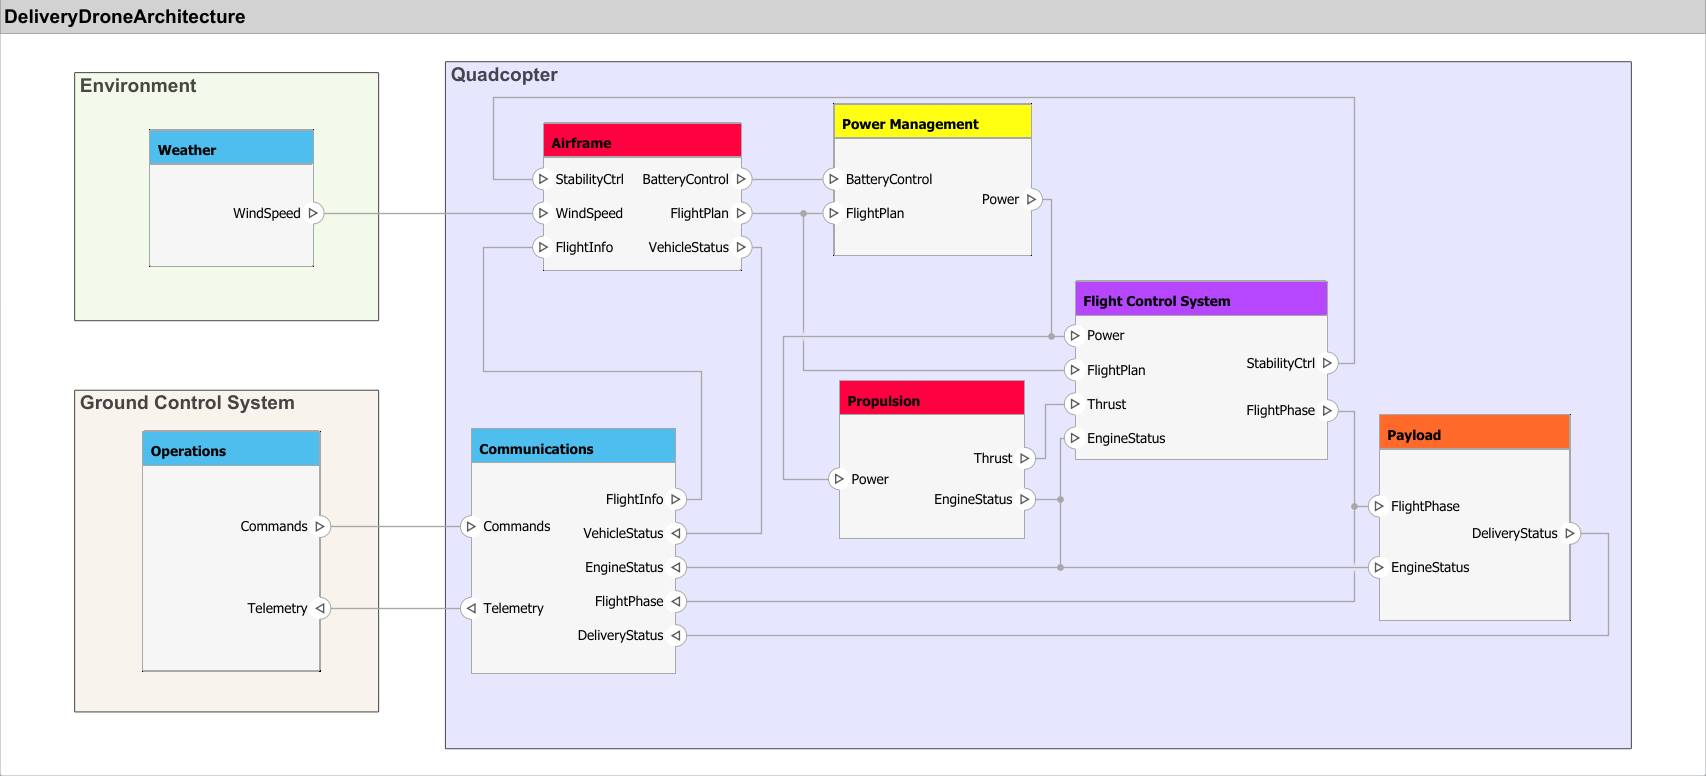

**This diagram is a simplified representation of a general quadcopter's interconnected systems. It does not depict the exact model we will be building, nor does it include all possible connections. Instead, it serves as a conceptual guide to illustrate how various systems can influence one another.** The lines show the interconnections between systems and thus, how the data flows. This diagram was created with a general color-coding scheme in [System Composer](https://www.mathworks.com/products/system-composer.html). In this example, specific colors have been assigned to represent certain systems as follows:

For reference, the model that was used to create this diagram can be accessed using the following button:

 

% Check if project is open. If not, add folders to path.
try
    % Open Simulink model for drone architecture
    open_system("Models/DeliveryDroneArchitecture.slx");
catch ME
    curloc = matlab.desktop.editor.getActiveFilename;
    rootdir = extractBefore(curloc,filesep+"Scripts");
    addpath(genpath(rootdir));
    open_system("Models/DeliveryDroneArchitecture.slx");
end

### Component Level

In the [Systems Decomposition](matlab:open('./SystemsDecomposition.mlx')) script, the software of the Flight Control System (FCS) was evaluated as a component. We initially designed one function of the FCS, the hover module. During the integration stage, the other modules (or components) must be added in order to complete the functionality of the FCS. Let's review some of the other FCS function requirements:

  **Try**. Explore the following flight control software model and utilize the rotary switch to change between flight phases. You can find the switch in the light blue panel on the left of the model. Click the run   button to simulate the model. Then, open the scope block labeled "Results" to observe the behaviors modeled across the different phases of flight. 

 **Pro-tip. **If the scope signals do not display properly, use the "scale x & y axes limits" button to bring the signal into view. In MATLAB 2025a, hover over the plot and select  . In versions prior to 2025a, use the   button.

 **Note**. Keep this model open for the other activities in this section!

 

% Check if project is open and add path
if isempty(matlab.project.rootProject)
    addpath(genpath(pwd));
end

% Open Simulink model for flight control software modules
open_system("Models/FlightControlSoftwareModules.slx");

During system decomposition, the component modeled was for the hover module. With the model open, use the following button to view the profile of the quadcopter's hover function:

 

% Run the model for the hover module and store data from simulation
set_param('FlightControlSoftwareModules/Desired Velocity/Flight Phase','Value',num2str(3));
flightData = sim("Models/FlightControlSoftwareModules.slx","StopTime","50");
posH = flightData.logsout{1}.Values.Data;
tvecH = flightData.logsout{1}.Values.Time;

% Plot results of flight data
plot(tvecH,posH,'SeriesIndex',4,'LineWidth',2);
xlim([0 50]);
ylim([0 90]);
xlabel('Time (sec)')
ylabel('Altitude (m)')
title('Module Data for Hover Flight Phase')
legend('Hover','Location','north')

As we integrate other components (like other flight control modules), the goal is to understand how each module works together within the FCS software and ultimately, how it affects the quadcopter. Previously, we were only able to generate code from a model with the purpose of hovering. Now, it is possible to generate code from a model that defines an entire mission profile. Use the following button to view the full mission profile of all the quadcopter's flight modules:

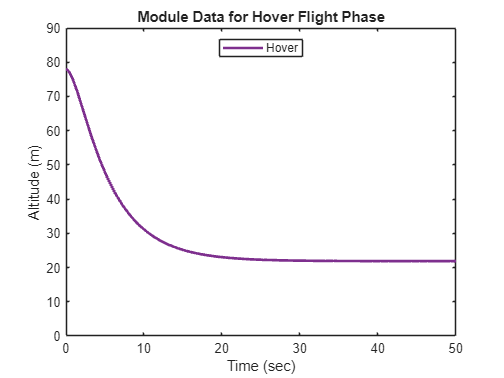

 

% Run the model for the flight phases and store data from simulation
pos = cell(5,1);
tvec = cell(5,1);
for phase = 1:5
    set_param('FlightControlSoftwareModules/Desired Velocity/Flight Phase','Value',num2str(phase-1));
    flightData = sim("Models/FlightControlSoftwareModules.slx","StopTime","50");
    pos{phase,1} = flightData.logsout{1}.Values.Data;
    tvec{phase,1} = (0:numel(pos{phase,1})-1)';
    if phase > 1

        tvec{phase,1} = tvec{phase,1} + tvec{phase-1}(end);
    end
end

% Plot results of flight data
plot(tvec{1},pos{1},'-.',tvec{2},pos{2},'-',tvec{3},pos{3},':',tvec{4},pos{4},'-.',tvec{5},pos{5},'--','LineWidth',2);
xlim([0 415]);
ylim([-10 90]);
xlabel('Time (sec)')
ylabel('Altitude (m)')
title('Mission Profile for All Flight Phases')
legend('Standby','Takeoff','Cruise','Hover','Landing','Location','best')

### Systems Level

 **Exercise 2. **Upon completion of the FCS component integration, what would be the next logical systems to integrate with the FCS? Please select all that apply and click the **Submit Answer** button below. Hint: Refer back to the system architecture.

exerciseSol2(...
    A = true, ...
    B = false, ...
    C = true, ...
    D = false);
 

Upon successful integration of components, combining systems is the next task in the process. In the previous section, the FCS was fully integrated and tested. Now, we need to start combining this system with others to see how they function as a unit. Let's take a look at a some other systems in the quadcopter; specifically the power management and propulsion systems. The power management system receives information about the aircraft and the demand required to provide power to other systems. The propulsion system receives power from the power management system to provide thrust for the quadcopter. This brings an added complexity to integration because of the multiple domains involved for this interaction to function. Referring back to the architecture table, our goal is to interface an electrical system with a mechanical system. Let's review some of the interface requirements for the **Power Management** and **Propulsion** systems:

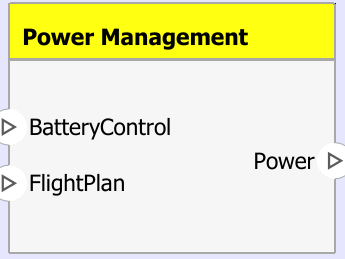        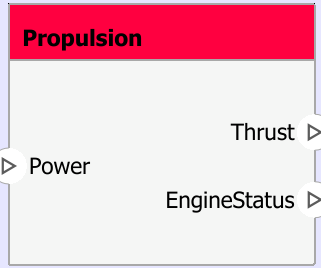

From a broader perspective, all four engines of the quadcopter must operate in unison to maintain stable flight and ensure safety of the payload. As we integrate these systems, it's essential to examine how each engine responds when power is supplied by the battery. To explore this further, let's consider a test scenario that simulates an actual flight:

- A 30 minute (1800 simulation seconds) round-trip flight with **no payload** that can be achieved with a fully charged 1200 mAh battery.

  **Try**. Open the following system integration model for the power management and propulsion systems. Use the toggle switches in the control panel (in the light blue panel to the left of the model window) to turn on each quadcopter engine separately. Observe the behavior of the system as you turn on each engine and then click the run   button. In the **Sensing** section of the model, you can view the battery charge in the scope block. 

 **Pro-tip. **If the control panel disappears, go to the **Panel** tab in the MATLAB toolstrip and select "Manage Panels" to bring the panel back into view.

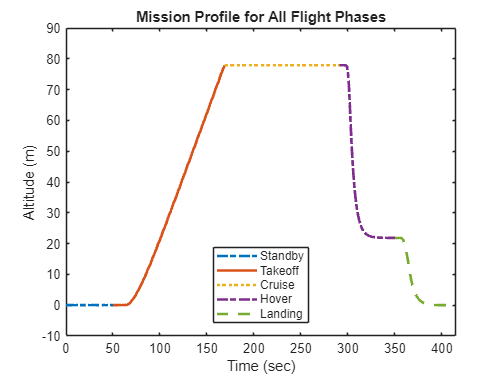


% Close previous model
close_system("Models/FlightControlSoftwareModules.slx",0);

% Open Simulink model for power management and propulsion system integration
open_system("Models/PropPowerSystemIntegration.slx");

Correct! Propulsion and Power Management would be reasonable systems to integrate with the FCS next.


  **Try**. Test the integration of each engine's load (propulsion system) on the battery (power management system). This will allow us to investigate the expected system performance and understand what the model is telling us. Use the following button to see the summary of results for this integration model.

 

% Print observations of the model
warning('off','physmod:simscape:engine:core:dae_errors:IcDiagnostics');
warning('off','physmod:simscape:simtypes:assert:Assertion');
warning('off','physmod:simscape:engine:core:dae_errors:IcSolveFirstFallback');
% Set model with different engine configurations
for iter = 1:4
    set_param(['PropPowerSystemIntegration/Engine Status/Prop ' num2str(iter) ' Status'],'Value',num2str(0));
end
 disp('The model is currently running different scenarios. Please be patient as the data prints out...');
% Run model with different engine configurations 
for obs = 1:4
    set_param(['PropPowerSystemIntegration/Engine Status/Prop ' num2str(obs) ' Status'],'Value',num2str(1));
    SysObs = sim("Models/PropPowerSystemIntegration.slx","StopTime","1800");

    % Find the index when the battery hits 0% charge (rounded to nearest integer)
    if SysObs.logsout{1}.Values.Data(end) > 0
        idx = numel(SysObs.logsout{1}.Values.Data);
    else

The model is currently running different scenarios. Please be patient as the data prints out...


        idx = find(SysObs.logsout{1}.Values.Data < 0.5,1,'first');
    end

    % Adjust grammar of output sentence
    if obs == 1
        engines = "1 engine";
    else 
        engines = obs + " engines";
    end

    % Output information on model run
    disp("The model is simulating " + engines + " running. The battery charge falls to " + round(SysObs.logsout{1}.Values.Data(idx)) + "% at " + round(SysObs.logsout{1}.Values.Time(idx)/60) + " minutes into the mission.");
end

The model is simulating 1 engine running. The battery charge falls to 4% at 30 minutes into the mission.
The model is simulating 2 engines running. The battery charge falls to 1% at 30 minutes into the mission.
The model is simulating 3 engines running. The battery charge falls to 0% at 26 minutes into the mission.
The model is simulating 4 engines running. The battery charge falls to 0% at 22 minutes into the mission.


Based on the results, it is apparent that the quadcopter would not be able to complete its 30-minute mission using all four engines (or even three!). The other crucial detail in this is that a payload hasn't been attached yet! In this scenario, the quadcopter runs out of power at 22 minutes! This tells us that the battery that was chosen to power the quadcopter was undersized. How do we feel about finding this issue out this far into our design? Realistically, the proper battery design should have been defined during the requirements and systems [decomposition phase](matlab:open('./SystemsDecomposition.mlx')). This reemphasizes the importance of trade studies to ensure that the correct battery size is chosen to support the performance required. To change requirements this late in the design would incur significant cost increases and time delays for delivery to the customer. This is because it isn't as simple as choosing a larger battery to meet the performance needs. All the requirements that were tested must be rewritten and tested again with the new definition of the battery. In addition, a review will be needed for understanding how changing this battery may impact other systems as described in the architecture.

To advance our integration narrative, let's assume a correctly sized battery had been selected, with a well-integrated power management and propulsion system. Initially, a 1200 mAh battery was used, but for successful mission completion, a 2400 mAh battery has been chosen. With our properly-sized battery, we can continue building up the product by adding the fully defined flight control system (FCS). Notice that the original FCS had a data table to define the lift force and thus the altitude of the quadcopter. This latest integration model has electric motors driving propellers as the physical representation of the lift force. This is an improvement in model fidelity of the design as the components and systems have become more refined. Let's review the FCS requirements:

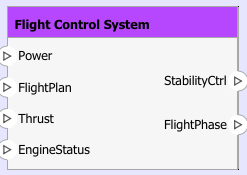

  **Try**. Open and run the multi-system integration model using the following button. This model accounts for no payload and a weight of 7 kg for the quadcopter. We will compare the results of the high fidelity hover flight model with those of the previous low fidelity version. The results will appear in this script. You may also take time to explore the model to understand the integration of the flight control system.

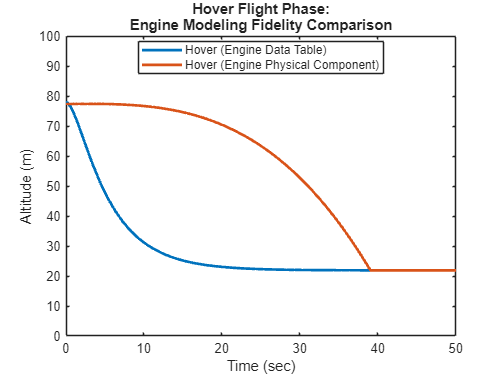

 

% Close previous model
close_system("Models/PropPowerSystemIntegration.slx",0);

% Open Simulink model for Propulsion, Power, and Flight Control system integration
open_system("Models/PropPowerCtrlSystemIntegration.slx");

% Load hover module data
load HoverData.mat;
posH = flightData.logsout{1}.Values.Data;
tvecH = flightData.logsout{1}.Values.Time;

% Run the model for the Propulsion, Power, and Flight Control integration and store data from simulation
set_param('PropPowerCtrlSystemIntegration/Desired Velocity/Flight Phase','Value',num2str(3));
finalData = sim("Models/PropPowerCtrlSystemIntegration.slx","StopTime","50");
posF = finalData.logsout{1}.Values.Data;
tvecF = finalData.logsout{1}.Values.Time;

% Plot results of flight data
plot(tvecH,posH,tvecF,posF,'LineWidth',2);
xlim([0 50]);
ylim([0 100]);
xlabel('Time (sec)')
ylabel('Altitude (m)')
title("Hover Flight Phase:" + newline + "Engine Modeling Fidelity Comparison")
legend('Hover (Engine Data Table)','Hover (Engine Physical Component)','Location','best')


% Feedback
pause(1)
warning("The comparison plot shows the model with the data table has the quadcopter descending faster than the model with the physical" + newline + "components. From another perspective, the descent of the quadcopter takes longer with the physical component representation." + newline + "This may seem trivial until you take remaining battery charge or planning a descent profile for a delivery into consideration.")

Until now, our focus has been on direct system interactions and testing. But what about integrating systems that are not directly connected, such as communication networks, where devices receive external data to inform decision making? As the quadcopter navigates toward its destination, it may encounter weather conditions that affect its stability and increase power demands. By using this data, the quadcopter can adjust its flight path to improve performance and ensure mission success. Let's review the **Weather** system requirement:

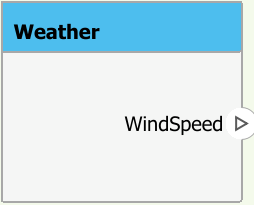

Consider a data system for a quadcopter that reports wind speed in real time. In order for on-board receivers to learn about the wind conditions instantly, the information must be transmitted from sensors on the ground that are measuring wind speed. This requires the use of the Internet of Things (IoT). One IoT service that can achieve this is [ThingSpeak](https://www.mathworks.com/products/thingspeak.html). Let's look at a quadcopter mission scenario taking place in Natick, Massachusetts, USA, where MathWorks is headquartered:

  **Try**. Access the "[WeatherStation](https://thingspeak.mathworks.com/channels/12397)" channel on ThingSpeak to retrieve the latest 10 wind speed measurements from ground-based sensors located in Natick, MA.

 

% Pull wind speed data using Thingspeak
data = thingSpeakRead(12397,NumPoints = 10,OutputFormat = 'TimeTable')

data = 10×8 timetable
         Timestamps         WindDirectionNorth0Degrees    WindSpeedmph    Humidity    TemperatureF    RainInchesminute    PressureHg    PowerLevelV    LightIntensity
    ____________________    __________________________    ____________    ________    ____________    ________________    __________    ___________    ______________

    15-Sep-2025 15:38:02                207                    4.4            0            0.1             0.011          {'30.04'}        4.093             0       
    15-Sep-2025 15:39:02                216                    0.3            0            0.1                 0          {'30.04'}        

windData =  data{:,2}

windData =     4.4000
    0.3000
    1.3000
    2.5000
    3.0000
    1.5000
    1.5000
    4.8000
    4.1000
   40.7000


 **Note**. There are other ways in which IoT can be used for monitoring systems. Imagine IoT sensors on-board the quadcopter that monitor engine status. This information can be transmitted back to the **Operations** system to understand the health of the quadcopter's propulsion system.

 **Exercise 3. **Wind speed can impact the mission of the quadcopter. What would be the best way to apply the wind speed data to the model?

exerciseSol3("Drag Force"); 

Correct! Because wind speed is part of natural air flow, drag is the most reasonable representation of wind speed.


  **Try**. Open and run the final integration model. This model accounts for no payload and a weight of 7 kg for the quadcopter. This time, we will compare the high fidelity hover flight model results both with and without wind effects. For simplicity, we will take the average of the latest 10 wind speed measurements. The results will appear in this script. You may also take time to explore the model to understand the integration of the weather system.

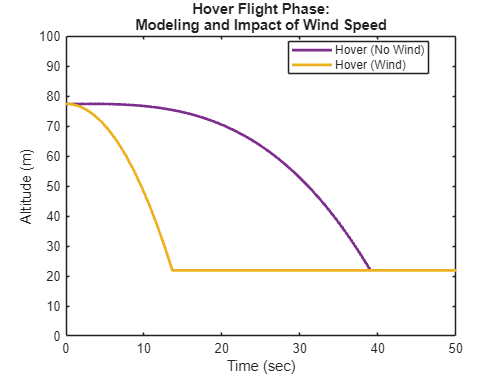

 

% Close previous model
close_system("Models/PropPowerCtrlSystemIntegration.slx",0);

% Open Simulink model for final system integration
open_system("Models/FinalSystemIntegration.slx");

% Take the average of the wind speed collected. Provide a test
% windspeed when local sensors are not reporting wind speed
if isequal(mean(windData),0) || lt(mean(windData),1)
    windAvg = 5;
    warning("The data being displayed is test data to see a difference in the models." + newline + "This is either because the Thingspeak channel is not currently providing up-to-date" + newline + "wind data or it is a very calm day with minimal winds.")
else
    windAvg = mean(windData);
end
windSpeed = [0,windAvg;50,windAvg];

% Run the model for the final integration and store data from simulation (no wind)
set_param('FinalSystemIntegration/Desired Velocity/Flight Phase','Value',num2str(3));
set_param('FinalSystemIntegration/Flight Phase Modules /Hover Module/T//F','Value',num2str(0));
finalData = sim("Models/FinalSystemIntegration.slx","StopTime","50");
posF = finalData.logsout{1}.Values.Data;
tvecF = finalData.logsout{1}.Values.Time;

% Second run for inclusion of wind
set_param('FinalSystemIntegration/Flight Phase Modules /Hover Module/T//F','Value',num2str(1));
finalData = sim("Models/FinalSystemIntegration.slx","StopTime","50");
posW = finalData.logsout{1}.Values.Data;
tvecW = finalData.logsout{1}.Values.Time;

% Plot results of flight data
plot(tvecF,posF,'SeriesIndex',4,'LineWidth',2);
hold on
plot(tvecW,posW,'SeriesIndex',3,'LineWidth',2);
xlim([0 50]);
ylim([0 100]);
xlabel('Time (sec)')
ylabel('Altitude (m)')
title("Hover Flight Phase:" + newline + "Modeling and Impact of Wind Speed")
legend('Hover (No Wind)','Hover (Wind)','Location','best')
hold off

 **Reflect.** What do you observe when considering the impact of wind? The model's results are limited to the average of the **latest 10 wind speed data points**. This means that every time the data is retrieved, the hover results will be different. *Consider taking 1000 data points for a specific time of the day. In addition, those data points coincide with model time steps that cover the total simulation time*. How would we achieve this? Would your results be more consistent?

### Product Level

This phase of integration fully combines the remaining systems for implementation, focusing on their interconnectivity to satisfy product level requirements. Some key areas of focus during this phase include review of system specifications, confirmation of outputs from data interfaces, and multi-domain system-level testing. If we follow the same process we have up until now, we will eventually reach full integration of all systems. At which point, we will have successfully integrated our final product. With a finished product, we must go back and ensure that we have met the intent of the design for the customer. Let's review the product level problem statement and requirements of the quadcopter:

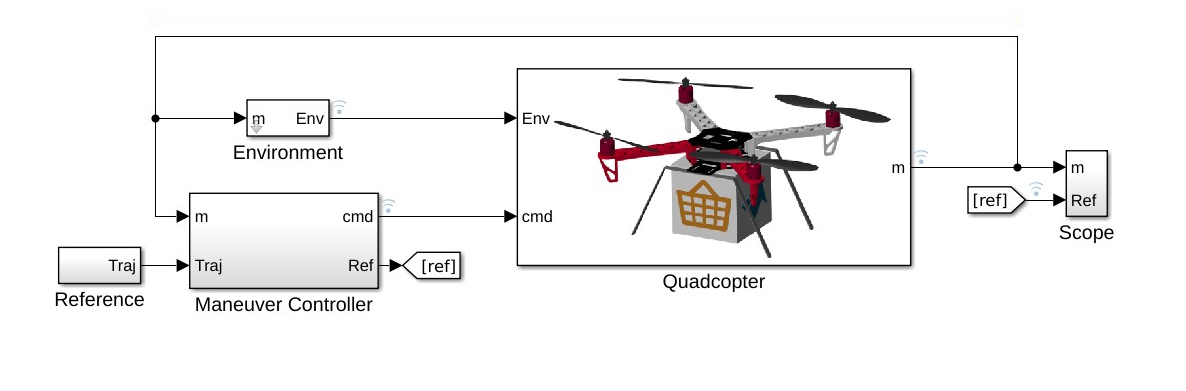

** Application.** We have arrived at the complete version of the quadcopter after system integration. It is now time to test at the product level to ensure it meets customer expectations. We will create requirements and test for this model based on the table above. If you need a refresher on creating requirements and tests, please revisit the [Defining Requirements](matlab:open('./DefiningRequirements.mlx')) script. Let's open the fully-integrated quadcopter [1] model using the button below. Once the model is open, return to the instructions in this script.

 **Warning. **If you are currently viewing this script in MATLAB Online, the following button will open a new instance of MATLAB Online to view the drone model, and therefore exit out of this script. To return to this script, use/copy/save this link: [**Integration And Test**](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Engineering-Problem-Solving&project=EngineeringProblemSolving.prj&file=Scripts/IntegrationAndTest.mlx)**. **Another option is to open the Integration and Test script on the MATLAB desktop while the drone model is open in MATLAB Online.

 

% Close previous model
close_system("Models/FinalSystemIntegration.slx",0);

% Open drone project in MATLAB Online
web('https://matlab.mathworks.com/open/github/v1?repo=mathworks/Quadcopter-Drone-Model-Simscape&project=Quadcopter_Drone.prj');

 **Pro-tip. **If the model is too small, you can expand the model window by dragging the corners. Next, click on the blank space in the model canvas and press the space button. This will resize the model for easier viewing.

  **Pro-tip**. Be sure to save your work often in MATLAB Online, as it will timeout after a certain period of inactivity and restart with a fresh session.

  **Try**. **In MATLAB Online**, create requirements for the product level quadcopter. Use the following code in the command window to open the Requirements Editor:

 Here is a list of the tasks to complete this activity:

- Create a new requirement set called `DroneReqx`.

- Create two parent requirements as written in the requirements table above.

- Link each requirement to a block in the model (# 1 >> "Package"  and # 2 >> "Battery").

- Add Verification Status column to the editor.

- Use the save button to "Save All".

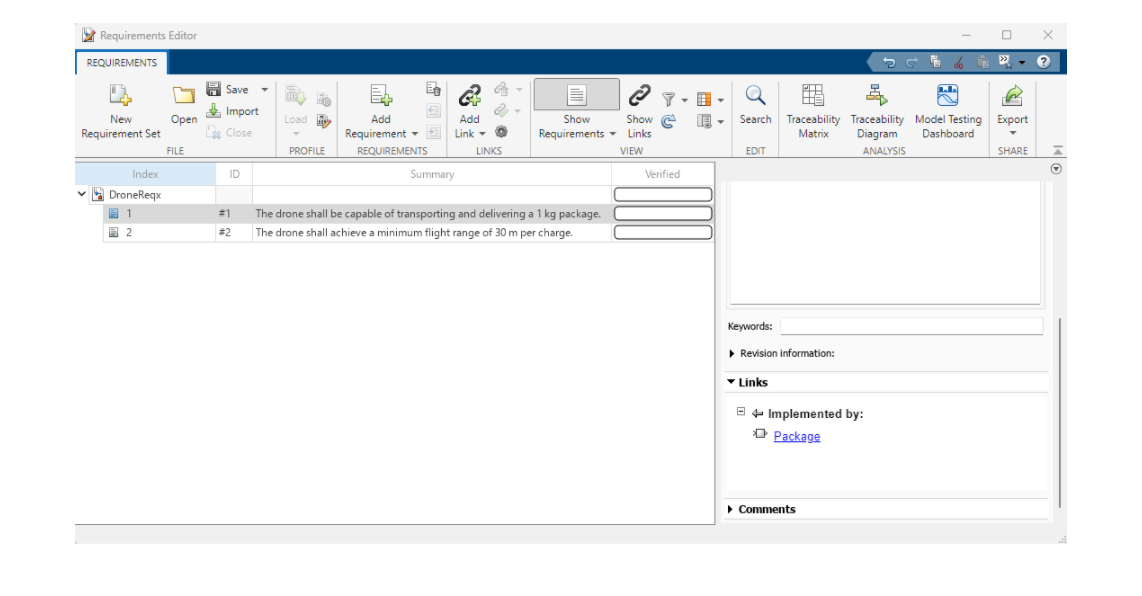

reqFlag = true;
% Display image of expected requirement set result
if reqFlag
    I = imread("Images/DroneReq.png"); %#ok<UNRCH>
    J = imresize(I,1);
    imshow(J,Interpolation="bilinear");
end

  **Try**. **In MATLAB Online**, create tests for the product level quadcopter. Use the following code in the command window to open the Simulink Test Manager:

 Here is a list of the tasks to complete this activity:

- Create a new test file called `DroneTests`.

- Create one new baseline test case under the test suite.

- Rename the test suite to Drone Test Suite and the test cases to Mass Test and Range Test.

- Link each test case to the model and its respective requirement.

- Update simulation stop time value for each test case to `145.8613.`

- In the cleanup callback for the Mass Test, enter the following code:

- In the cleanup callback for the Range Test, enter the following code:

- Use the save button to "Save All".

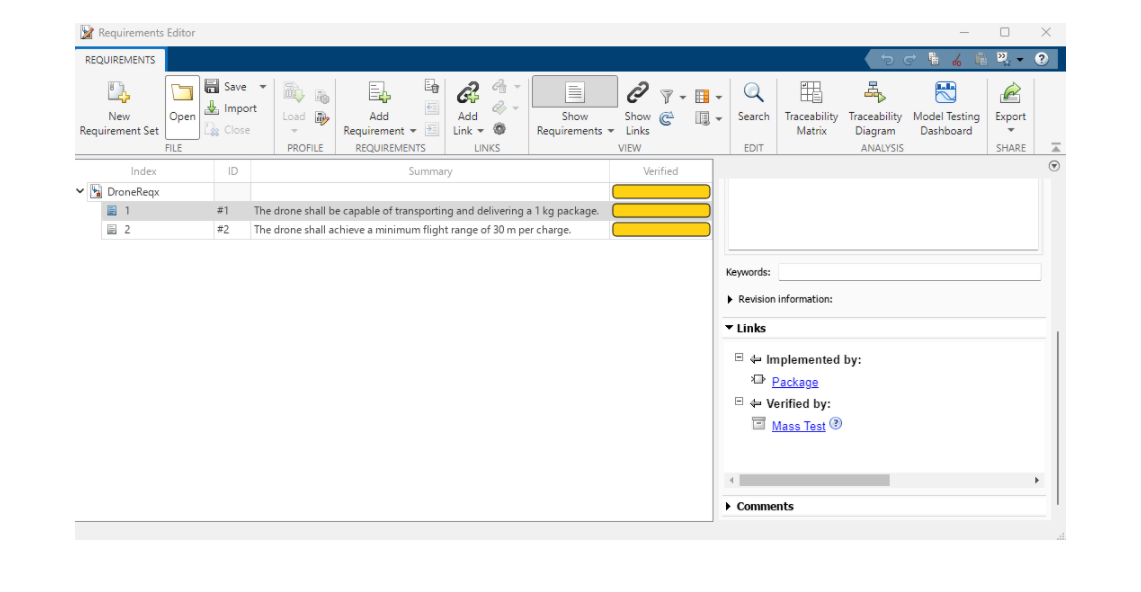

testFlag = true;
% Display image of expected test set result
if testFlag
    I = imread("Images/DroneTest.png"); %#ok<UNRCH>
    J = imresize(I,1);
    imshow(J,Interpolation="bilinear");
end

## Complete Design

With a complete design, this means the components, systems, and product requirements have been met. Keep in mind that beyond the product requirements, [regulatory requirements](matlab:open('./DefiningRequirements.mlx')) must be satisfied as well for legal usage. Good designs ensure regulatory requirements are encapsulated in the component and system requirements. Throughout this process, it is very possible to find issues in defined requirements and system connections that could drive a redesign or modification. At this point, that is a costly exercise but necessary if the customer needs are not being met. The emphasis on spending the most time and effort in the requirements and decomposition phases are paramount to ensure a smoother integration process and thus, a successful complete design. 

### Design Validation (Simulation)

On the right side of the V-model, the focus is on validation. The most effective way to describe validation activities is by answering a key question: Did we satisfy the product requirements that support the customer needs? Or, more simply, did we build the right quadcopter?

Satisfying the product requirements can be straightforward, provided the system's requirements have been properly defined and evaluated. Let's examine the requirements and validation tests for the overall quadcopter product.

  **Try**. **In MATLAB Online, **with the Simulink Test Manager window open, select the "Drone Test Suite" in the test browser and click the run   button to simulate the model.

 

% Display success message
disp("Well done! All product level tests have passed and you have successfully validated your design!");

Well done! All product level tests have passed and you have successfully validated your design!


### Design Validation (Hands-on)

While a simulation check is efficient for validation of a model, let's try a more hands-on approach to validating the requirements of the product.

 **Exercise 4. In MATLAB Online's command window**, validate the mass of the package using the following equation: $m = \rho V$, where $m$ is mass, $\rho$ is density, and $V$ is volume.

The package's mass is defined by its *cube-shaped* geometry using the variables `pkgSize` $(m)$ and `pkgDensity` $\left(\frac{kg}{m^3}\right)$. The variable `pkgSize` is in the form of $(Length*Width*Height)$.

exerciseSol4("1 kg");

Correct! This satisfies the requirement for mass.


 **Reflect. **What would happen if we chose to use a package mass of 5 kg instead? How would you achieve that if the model is based on geometry? After calculating an answer, update the variable in the MATLAB Online workspace and run the model. Once the model is run, what do you observe in the visualization?

 **Exercise 5. In MATLAB Online's command window**, validate the range (total distance) traveled by the quadcopter using the following equations: $d_{Total} = \sum_{i=1}^n d_i$, where $n = 4$ & $d_i = \sqrt{(x_{i+1}-x_i)^2+(y_{i+1}-y_i)^2+(z_{i+1}-z_i)^2}$.

The mission path is defined by 5 sets of waypoints in 3D space, for a one-way trip. Each distance between the waypoints can be treated as a vector and calculated based on the formulas above. Multiply your final answer for $d_{Total}$ by 2 before submission. This is to account for the round-trip of the quadcopter. The waypoints can be viewed by using the following code:

 **Pro-tip. **To visualize the mission path, select the 2nd hyperlink titled "**2. Plot Trajectory**" on the top-level of the quadcopter model in MATLAB Online.

exerciseSol5(34);  

Correct! This satisfies the requirement for range.


 **Reflect. **To visualize the battery charge, select the 3rd hyperlink titled "**3. Plot Currents and Battery SOC**". From the plot, estimate the initial and final charge values. To calculate the remaining battery life percentage, use the following equation: $\frac{Charge_{Initial}}{Charge_{Final}}*100$. What do you observe about the battery charge in relation to our range requirement?

With all of our requirements meeting our expected results, we have high confidence that our product design is correct and ready to be delivered to our customer!

## Customer Delivery/Acceptance and Moving Forward

Finally! All the planning and organization has paid off! To get to this step means that Your team is now ready to deliver the quadcopter to Sundaland, Inc. Specifications and information will be provided to Sundaland about their newly designed quadcopter. Even with acceptance of the quadcopter, the work does not stop here. If Sundaland encounters any issues with their quadcopter in service, they will be sure to be in contact with your team. Providing support and maintenance for your product after delivery is another part of the life cycle. This phase can involve software patches or updates, hardware upgrades and more for as long as the quadcopter remains operational. 

### Digital Twins

Now what remains of your team in building quadcopters? If we look back, the process of building a drone from scratch was not easy, and if possible, avoiding a lot of these headaches would be beneficial. In addition, there may be a market for building more drones with different capabilities. Ideally, your team would want to improve, scale, or upgrade the design to support a wider array of customers. With a digital twin, it is possible to continuously improve the design of your product without excessive amounts of rework. This type of digital model mimics the real world product and is validated based on product operational and test data. A few benefits of digital twins are:

- Enable faster development of newer products and customization

- Reduces costs associated with better planning and minimized waste

- Improve reliability and uptime through real-time monitoring and predictive maintenance using physical sensors 

- Complete life cycle management from development to retirement

Throughout real-world integration and test, physical assembly of systems would occur to ensure proper functionality. Since we are not physically assembling a product in this script, we have represented the drone assembly with a virtual model, which is a digital twin. It represents our design and test data having one to one mapping with a real-world quadcopter.

 **Exercise 6. **In relation to the benefits of digital twins, which of the following applies to the drone model? Please select **one** option and click the **Submit Answer** button below. 

exerciseSol6(...
    A = false, ...
    B = false, ...
    C = false, ...
    D = false, ...
    E = true);

Correct! These are all benefits that the drone digital twin model can achieve.


** Demonstration**. Explore a digital twin model of a triplex hydraulic pump [2] and its predictive maintenance algorithm for detecting failing parts using the button below. 

 **Warning. **If you are currently viewing this script in MATLAB Online, the following button will open a new instance of MATLAB Online to view the drone model, and therefore exit out of this script. To return to this script, use/copy/save this link: [**Integration And Test**](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Engineering-Problem-Solving&project=EngineeringProblemSolving.prj&file=Scripts/IntegrationAndTest.mlx)

 

% Open predictive maintenance pump in MATLAB Online
web('https://matlab.mathworks.com/open/fileexchange/v1?id=65605&project=Triplex_Pump.prj');

 **Pro-tip. **If the model is too small, you can expand the model window by dragging the corners. Next, click on the blank space in the model canvas and press the space button. This will resize the model for easier viewing.

  **Try. **After the "Triplex Pump with Faults Overview" script opens, scroll down to the "Model" section and select the "**Open Triplex Pump Model**" link. Click the run   button in the model to simulate the "No Fault" scenario. The multibody explorer will open and animate the pump's motion. After simulation, select the "Simscape Results" button in the explorer toolstrip. In the model tree navigator, go to the *Pump --> Plunger 1 or 2 --> Flow in --> Hydraulic Flow Rate Sensor --> V (Volumetric Flow Rate). Compare* the flow rates between plunger 1 & 2. Use CTRL + Click on "V" to overlay the signals on the same plot.

  **Try. **In the same script, go to the "Configure Model" section. For *Plunger 1*, select "On" for the seal leak and "On" for the blocked inlet. Return to the open model and click the run   button to simulate the "Fault" scenario. The red objects in the multibody explorer are the failures that were selected. Follow the same post-simulation steps as the previous interaction.

 **Note.** For exploring *Predictive maintenance* of the pump, select the "**Preprocess Measured Data from Pump**" and "**Create Training Data and Develop Predictive Maintenance Algorithm**" links at the top of the main script.

Upon completion of the previous activities, let's clean up our working environment:

 

% Check if project is open. If not, remove folders to path.
if isempty(matlab.project.rootProject)
    curloc = matlab.desktop.editor.getActiveFilename;
    rootdir = extractBefore(curloc,filesep+"Scripts");
    rmpath(genpath(rootdir));
else
    ...
end

## Next Steps

You have successfully completed the Engineering Problem Solving module. You are encouraged to take the skills learned from this set of modules and apply them in the real world! Additionally, take some time to explore the tools and resources in the Further Exploration section to expand your knowledge on solving problems with systems thinking.

## Further Exploration

- [Digital Twins](https://www.mathworks.com/discovery/digital-twin.html)

- [Model-Based Systems Engineering](https://www.mathworks.com/solutions/model-based-systems-engineering.html)

- [Systems Engineering with MATLAB](https://www.mathworks.com/help/overview/systems-engineering.html)

- [Video Series - Systems Engineering: Managing System Complexity](https://www.mathworks.com/videos/series/systems-engineering.html)

- [Coursera: MathWorks Systems Engineering Course](https://www.coursera.org/learn/systems-engineering-mathworks)

## Glossary

**V-model** - A graphical representation of the systems development life cycle. (↑ Return to Text)

**Problem Statement **- A statement that concisely describes a problem and the needs that must be addressed, showing the gap between current and desired state. (↑ Return to Text)

**Requirement** - A documented need or condition that a particular product, service, or system must satisfy. (↑ Return to Text)

**Trade Study **-  A process where different options or solutions to a problem are compared against a set of criteria to identify the most balanced and optimal choice. (↑ Return to Text)

**Internet of Things **- A vast network of interconnected devices that can collect and exchange data via the internet. (↑ Return to Text)

**Validation **- The action of confirming the accuracy of the solution being implemented is correct. (↑ Return to Text)

**Digital Twin **- A digital representation of a product, process, or system either in operation or in development. (↑ Return to Text)

**Predictive Maintenance **- A strategy that uses data analysis and condition monitoring to anticipate when equipment is likely to fail, creating opportunity for proactive scheduled maintenance before a breakdown. (↑ Return to Text)

## References

[1] Miller, S. (2025, January 4). *Quadcopter Drone Model in Simscape*. Www.Mathworks.com. Retrieved June 23, 2025, from [https://www.mathworks.com/matlabcentral/fileexchange/63580-quadcopter-drone-model-in-simscape](https://www.mathworks.com/matlabcentral/fileexchange/63580-quadcopter-drone-model-in-simscape) (↑ Return to Text)

[2] Miller, S. (2025, January 4). *Predictive Maintenance in a Hydraulic Pump*. Www.Mathworks.com. Retrieved August 15, 2025, from [https://www.mathworks.com/matlabcentral/fileexchange/65605-predictive-maintenance-in-a-hydraulic-pump](https://www.mathworks.com/matlabcentral/fileexchange/65605-predictive-maintenance-in-a-hydraulic-pump) (↑ Return to Text)

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function exerciseSol1(opts)
    % Provides solution for Exercise 1
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
    end

    if ~any([opts.A opts.B opts.C opts.D])
        disp("Please make a selection.")
    elseif opts.A & ~[opts.B opts.C opts.D] %#ok<AND2>
        warning("Very close! Ensuring end-user expectations for the final product are met is not the main goal of integration and test. This is an activity that occurs after integration and test.")
    elseif opts.B & ~[opts.A opts.C opts.D] %#ok<AND2>
        disp("Correct! The goal is to combine components and systems into one functional system.")
    elseif opts.C & ~[opts.A opts.B opts.D] %#ok<AND2>
        warning("Incorrect. Gathering stakeholder requirements and defining system architecture occurs during system decomposition; the left side of the V-model.")
    elseif opts.D & ~[opts.A opts.B opts.C] %#ok<AND2>
        warning("Incorrect. Performance benchmarking of components happens during the system decomposition phase; the left side of the V-model.")
    else % Any other combination
        warning("Please be sure to select only one option!")
    end
end

function exerciseSol2(opts)
    % Provides solution for Exercise 2
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
    end

    if ~any([opts.A opts.B opts.C opts.D])
        disp("Please make a selection.")
    elseif [opts.A opts.C] & ~[ opts.B opts.D] %#ok<BDSCA,AND2>
        disp("Correct! Propulsion and Power Management would be reasonable systems to integrate with the FCS next.")
    elseif opts.B | opts.D %#ok<OR2>
        warning("Incorrect. Please make sure to review all that apply and refer back to the system architecture to verify your selections.")
    else % Any other combination
        warning("Partially correct. There is more than one right answer.")
    end
end

function exerciseSol3(choices)
    % Provides solution for Exercise 3
    arguments
        choices (1,1) string {mustBeMember(choices,["Select an answer" "Drag Force" "Gravitational Force" "Frictional Force" "Spring Force"])}
    end

    if choices == "Select an answer"
    else
        if choices == "Drag Force"
            disp("Correct! Because wind speed is part of natural air flow, drag is the most reasonable representation of wind speed.");
        elseif choices == "Gravitational Force"
            warning("Incorrect. While updrafts (+z) and downdrafts (-z) occur in the air, wind in the mid-latitudes (ex. Natick, MA) generally flow from west to east.");
        elseif choices == "Frictional Force"
            warning("Incorrect. Frictional Force is normally applied to contact between two physical surfaces and not in fluid (air) flow.");
        elseif choices == "Spring Force"
            warning("Incorrect. While the fluctuating force of wind can be represented by a spring in nature, it does not capture the true dynamic nature of wind.");
        end
    end
end

function exerciseSol4(choices)
    % Provides solution for Exercise 4
    arguments
        choices (1,1) string {mustBeMember(choices,["Select an answer" "2 kg" "1 kg" "10 kg" "1.5 kg"])}
    end

    if choices == "Select an answer"
    else
        if choices == "1 kg"
            disp("Correct! This satisfies the requirement for mass.");
        else
            warning("Incorrect! Try again.");
        end
    end
end

function exerciseSol5(dRange)
    % Provides solution for Exercise 5
    arguments
        dRange (1,1) double
    end

    errMargin = 1; % Meters
    if dRange >= (34.5234 - errMargin) && dRange <= (34.5234 + errMargin)
        disp("Correct! This satisfies the requirement for range.")
    elseif dRange == 0
        warning("Please enter an answer before submission.")
    else
        warning("Incorrect! Your answer has exceeded the tolerance of the possible solutions. Please ensure you mulitplied your total distance by 2.")
    end
end

function exerciseSol6(opts)
    % Provides solution for Exercise 6
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
        opts.E (1,1) logical
    end

    if ~any([opts.A opts.B opts.C opts.D opts.E])
        disp("Please make a selection.")
    elseif opts.E
        disp("Correct! These are all benefits that the drone digital twin model can achieve.")
    else % Any other combination
        warning("Incorrect. Please make sure to review all the benefits of digital twins and try again.")
    end
end